# ACM 11: Week 2 In-class exercise 1

## Order of accuracy for spatial finite differences

In this exercise we will explore several different finite difference schemes for approximating spatial differences. To do this, we will examine spatial discretization of the function $u=\sin \;\left(2\pi x\right)+\cos \left(\pi x\right)+e^x$ on the interval $\left\lbrack 0,1\right\rbrack$. The code block below sets up a computational grid with $n$ spaces and $n+1$ grid points.

% set up computational grid
n = 10000;
x = linspace(0,1,n+1);
dx = x(2)-x(1)

dx =                     0.0001


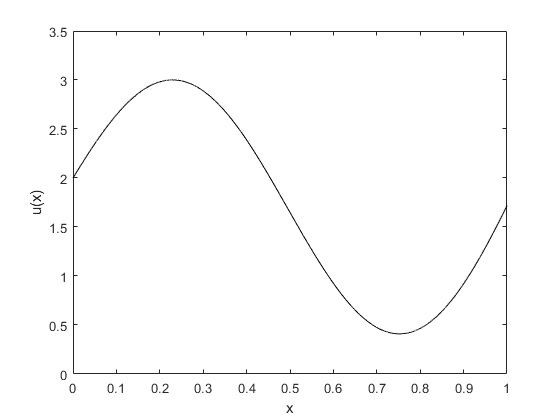


u = sin(2*pi*x) + cos(pi*x) + exp(x);

figure(1); clf
plot(x,u,'k'); xlabel('x'); ylabel('u(x)')

Let's approximate the first derivative of $u$. We will compare the true value of the spatial derivative, given by $u_x =2\pi \cos \left(2\pi x\right)-\pi \sin \left(\pi x\right)+e^x$, to the finite difference approximation of this derivative. We will first do this comparison for any interior grid point:

i = 5;  % pick which grid point to compare at, can be anything such that 0 < i < n+1

uxi_true  = 2*pi*cos(2*pi*x(i)) - pi*sin(pi*x(i)) + exp(x(i))    % true value of derivative at i-th grid point

uxi_true =           7.27961770246222


uxi_left  = (u(i) - u(i-1))/dx      % left approx. of derivative at i-th grid point

uxi_left =           7.28006571160122


uxi_right = (u(i+1) - u(i))/dx      % right approx. of derivative at i-th grid points

uxi_right =           7.27916886996027



err_i_left  = abs(uxi_true - uxi_left)    % error at i-th point using left difference

err_i_left =       0.000448009139006444


err_i_right = abs(uxi_true - uxi_right)   % error at i-th point using right difference

err_i_right =       0.000448832501945162


#### In-class activity: write your answers below each prompt and upload to Canvas when you are done (one upload per group is fine).

#### (0) Introduce yourselves to each other in the breakout room - name, optional pronouns, year, major, and house is good. Please list full names of all students in your group: 

Kyle McGraw

#### (1) Change up the number of grid points using the drop-down menu above. As $\Delta x\to 0$, we expect that first-order difference schemes scale linearly with the mesh size $\Delta x$. Verify that this is the case (note that this behavior is expected only for small $\Delta x$, and for small $n$ we may not see this linear scaling) by estimating the slope, $m$, of the line $\textrm{error}=m\Delta x\;$for both the left and right differences at small $\Delta x$.

$\Delta$x, left, right

0.1, 1.58, 0.82

0.01, 0.0889, 0.0967

0.001, 0.0049, 0.005

0.0001, 0.000448, 0.0004488

We see that the error goes nearly linearly with the errors being on the same order of magnitude as the $\Delta$x for all of the values. We would estimate the slope to be about 4.48 for the left error and 4.488 for the right error.

We now compare the difference scheme approximation to the true spatial derivative over the whole interval. A common way to compare errors across different grid sizes is to multiply the 2-norm of the error vector by $\sqrt{\Delta x}$. This is roughly the root-mean-square of the error (RMSE) over all the grid points. Another way to interpret this is as a numerical estimate of the $L^2 \left(\left\lbrack 0,1\right\rbrack \right)$-norm (square root of the integral of the squared function) of the error.

ux_true = 2*pi*cos(2*pi*x) - pi*sin(pi*x) + exp(x);             % this is the true first derivative, for reference

% difference approximation - whether this is left or right depends on if we use it to approximate the 
% derivative at x(1:end-1) or x(2:end)
ux_FD   = (u(2:end) - u(1:end-1))/dx;   

% calculate error for left and right differencing
err_left  = norm(ux_true(2:end) - ux_FD)*sqrt(dx)

err_left =        0.00172461464159735


err_right = norm(ux_true(1:end-1) - ux_FD)*sqrt(dx)

err_right =        0.00172461271399202


#### (2) As you did before, for the slope of the error scaling at a specific point, please provide an estimate of the slope of the error scaling, this time for the integrated error over the whole interval that you just calculated.

$\Delta$x, left, right

0.1, 1.7118, 1.7098

0.01, 0.17246, 0.17244

0.001, 0.017246, 0.017246

0.0001, 0.0017246, 0.0017246

We see that the error goes nearly linearly with the errors being one order of magnitude larger than the $\Delta$x for all of the values. We would estimate the slope to be about 0.0017246 for both errors.

#### (3) Now implement the second-order central difference in the below code block, and calculate the error at the i-th point as before as well as over the whole interval.

uxi_central     = (u(i+1) - u(i-1))/(2*dx)

uxi_central =           7.27961729078075


err_i_central   = abs(uxi_true - uxi_central)

err_i_central =       4.11681469358882e-07



ux_central      = (u(3:end) - u(1:end-2))/(2*dx);
err_central     = norm(ux_true(2:end-1) - ux_central)*sqrt(2*dx)

err_central =       4.38127806095501e-07


#### (4) How does the scaling of the central difference error differ from the scaling of the left and right difference errors above?

$\Delta$x, central xi, central

0.1, 0.37931, 0.39113

0.01, 0.00392, 0.00434

0.001, 0.0000411, 0.0000438

0.0001, 0.000000412, 0.000000438

We see that the error goes scales as the $\Delta$x squared instead of linearly with$\Delta$x as each time the $\Delta$x decreases by a factor of 10, the error decreases as a factor of 100.